# Chapter 7: Moving Beyond Linearity

## 7.8 Lab: Non-linear Modeling

clear all; clc; close all;
Wage = readtable("Data\Wage.csv", 'TreatAsEmpty',{'?','NA','N/A'},'ReadRowNames', true);
Wage.sex = categorical(Wage.sex);
Wage.maritl = categorical(Wage.maritl);
Wage.race = categorical(Wage.race);
Wage.education = categorical(Wage.education);
Wage.region = categorical(Wage.region);
Wage.jobclass = categorical(Wage.jobclass);
Wage.health = categorical(Wage.health);
Wage.health_ins = categorical(Wage.health_ins);
Wage.jobclass = categorical(Wage.jobclass);

### 7.8.1 Polynomial Regression and Step Functions

WageAge = Wage(:,{'age','wage'});
fit2 = fitlm(WageAge,'wage ~ age^4');
fit2.Coefficients

ans = 5×4 table
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)        -184.15         60.04    -3.0672     0.0021803
    age                 21.246        5.8867      3.609    0.00031236
    age^2             -0.56386       0.20611    -2.7357     0.0062606
    age^3            0.0068107     0.0030659     2.2214      0.026398
    age^4          -3.2038e-05    1.6414e-05    -1.9519      0.051039


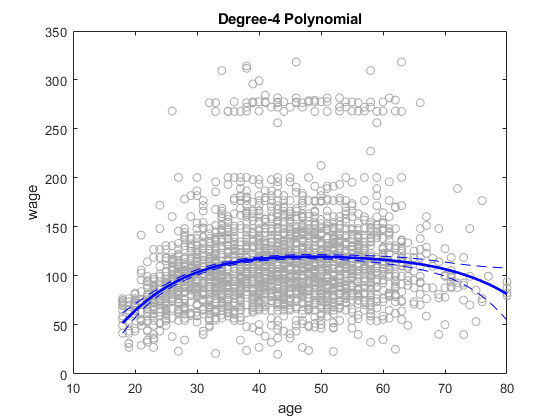

ageGrid = (min(WageAge.age):max(WageAge.age)).';
[preds2, yci2]= predict(fit2,ageGrid);
figure
plot(WageAge.age,WageAge.wage,'o','Color','#A9A9A9'); hold on
plot(ageGrid,preds2,'-','Color','b','LineWidth',2);
plot(ageGrid,yci2(:,1),'--',ageGrid,yci2(:,2),'--','Color','b');
xlabel('age');
ylabel('wage');
title 'Degree-4 Polynomial';
hold off

Performs an anova() analysis of variance (ANOVA, using an F-test) 

anova(fitlm(Wage,'wage ~ age^5'))

ans = 6×5 table
               SumSq        DF       MeanSq         F         pValue  
             __________    ____    __________    _______    __________

    age      1.9987e+05       1    1.9987e+05     125.44    1.4911e-28
    age^2    2.2879e+05       1    2.2879e+05     143.59    2.3677e-32
    age^3         15756       1         15756     9.8888     0.0016792
    age^4        6070.2       1        6070.2     3.8098      0.051046
    age^5        1282.6       1        1282.6    0.80498       0.36968
    Error    4.7703e+06    2994        1593.3                         


we can use anova() to compare these three models:

anova(fitlm(Wage,'wage ~ education + age^3'))

ans = 5×5 table
                   SumSq        DF       MeanSq        F         pValue   
                 __________    ____    __________    ______    ___________

    age          1.2773e+05       1    1.2773e+05    102.74      9.215e-24
    education    1.0579e+06       4    2.6447e+05    212.72    8.1717e-161
    age^2         1.426e+05       1     1.426e+05     114.7      2.729e-26
    age^3            5586.7       1        5586.7    4.4936       0.034104
    Error        3.7198e+06    2992        1243.3                         


WageLogistic = [table((Wage.wage > 250),'VariableNames',{'wage'}) Wage(:,'age')] ;
fit = fitglm(WageLogistic,'wage ~ age^4','Distribution','binomial');

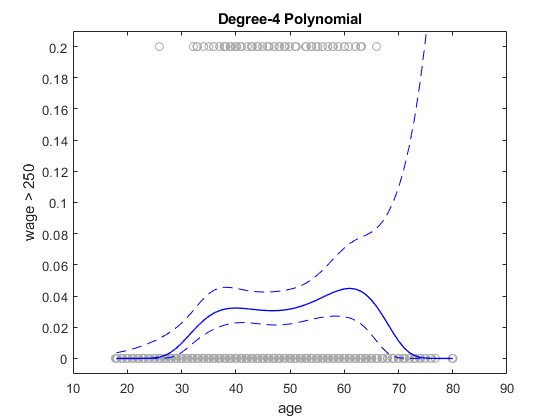

[b,~,stats] = glmfit([Wage.age, Wage.age.^2, Wage.age.^3, Wage.age.^4],(Wage.wage > 250),'binomial','link','probit');
[yhat,dylo,dyhi] = glmval(b,[ageGrid, ageGrid.^2, ageGrid.^3, ageGrid.^4],'probit',stats);
seBands = [yhat - dylo, yhat + dyhi];
figure
plot(jitter(Wage.age), (Wage.wage > 250)/5, 'o','Color','#A9A9A9');% darkgrey color
hold on
plot(ageGrid,yhat,'-','Color','b','LineWidth',1);
plot(ageGrid,seBands(:,1),'--',ageGrid,seBands(:,2),'--','Color','b');
ylim([-0.01, 0.21]);
xlabel('age'); ylabel('wage > 250');
title 'Degree-4 Polynomial';
hold off

Fit a step function, as discussed in Section 7.2

cut = linspace(min(Wage.age),max(Wage.age),5);
age(Wage.age >= cut(1) & Wage.age <= cut(2),:) = 1;
age(Wage.age > cut(2) & Wage.age <= cut(3),:) = 2;
age(Wage.age > cut(3) & Wage.age <= cut(4),:) = 3;
age(Wage.age > cut(4) & Wage.age <= cut(5),:) = 4;
cutTable = dummyvar(categorical(age));
fitStep = fitlm(cutTable(:,2:end),WageAge.wage,'PredictorVars',...
    {'cut(age, 4)(33.5,49]','cut(age, 4)(49,64.5]','cut(age, 4)(64.5,80.1]'});
fitStep.Coefficients

ans = 4×4 table
                              Estimate      SE      tStat       pValue  
                              ________    ______    ______    __________

    (Intercept)                94.158     1.4761     63.79             0
    cut(age, 4)(33.5,49]       24.053     1.8294    13.148    1.9823e-38
    cut(age, 4)(49,64.5]       23.665      2.068    11.443    1.0407e-29
    cut(age, 4)(64.5,80.1]     7.6406     4.9874     1.532       0.12564


### 7.8.2 Splines

% % Change the directory
% cd 'C:\Users\minhd\OneDrive\Desktop\Books Machine learning\An Introduction to Statistical Learning with Applications in R\ISLR_Python-master\Data\bspline'
% 
% % % MLStartDir("C:\Users\minhd\OneDrive\Desktop\Books Machine learning\An Introduction to Statistical Learning with Applications in R\ISLR_Python-master\Data\bspline")
% knots = [25*ones(1,3), [25, 40, 60], 60*ones(1,4)];
% % augknt([25, 40, 60],4);
% [B,~] = bspline_basismatrix(4,knots,sort(Wage.age));
% tau = linspace(min(Wage.age),max(Wage.age),length(Wage.age));
% k = 5;
% knots = augknt([25, 40, 60],k);
% colmat = spcol(knots,k,tau);
% quantile(Wage.age,0.5)
%  
% % k = 7;
% % Wage.age1 = linspace(0,1,100);
% % B = spcol(augknt(linspace(0,1,20),k), k, linspace(0,1,100)); 
% % B2 = spcol(augknt([quantile(Wage.age1,0.25),...
% % quantile(Wage.age1,0.5), quantile(Wage.age1,0.75)],5), 5, sort(Wage.age1)); 
% 
% % tau = linspace(0,pi,101); k = 4;
% % knots = augknt(linspace(0,pi,11),k);
% % colmat = spcol(knots,k,tau);

### 7.8.3 GAMs